# Design Phase Plots for Stabilization Problem and for tracking problem

**⚠️ IMPORTANT: **the data associated to these simulations are in the `sim_esp####` files. ⚠️

**Before exporting the figures select the time interval that allow to see well the carachteristics of the response!!! curently we plot up to t_max but something is hard to see we may need to zoom in!!!**

Here you will find the plots of the behaviour of the pendolum wrt to the worst initial conditions on alpha for each stabilizing controller. For each case it is also reported the simulation of the observer/KF.

For each case you will find the following plots:

In the Control design -> a plot with the voltage and a plot with all states behaviour starting from the worst initial conditions on alpha

In the observer design -> a plot with all estimated states and followed by single plots reporting signle state variables with their estimate. You can choose in the report to place the single plot of $\dot{\;\alpha }$ or the whole plot with all estimated states. In my view it is more convenient to place only the single plot with alpha dot.

**Use these plots to compute the performances of controllers in simulation, these performance must satisfy the specifications defined for each case.**

clear
close all
t_max = 5; % global variables for plots

## **Index to the Document**

You can click here instead of scrolling down to navigate more rapidly through the document and find the controller/observer that you need.

- Pole Placement Controller Design (Stabilization)

- Observer Design 

- LQ Controller Design (Stabilization)

- Kalman Filter

- Pole Placement Controller Design (Tracking)

- LQ Controller Design (Tracking)

- Robustness of tracking with respect to disturbances: PP vs LQ in simulation.

## Pole Placement Controller Design (Only with Observer during design)

back to Index

- `sim_esp1111`

- 
$$\alpha =0\ldotp 13\;\left\lbrack \textrm{rad}\right\rbrack$$


#### Specifications

- 
$$e_{\infty } =0\;$$


- settling time $t_s \le 1\ldotp 5\;\left\lbrack s\right\rbrack$ in worst conditions on alpha ($e<0\ldotp 02\times \left|y_{\textrm{final}} -y_{\textrm{initial}} \right|$) -> **Remark: **only alpha starts from a value which is different from 0 so the settling time with this definition can be used only for $\alpha$ variable. We can mention that, once this condition was satisfied we seen by inspection that the other state variable were enough close to zero. To be more precise I would still report the values for all the sate variables at the time instant at which the $\alpha$ can be considered to have been stabilized.

- Voltage allowed to saturate during the whole manuvre just for maximum $0\ldotp 1\;\left\lbrack s\right\rbrack$ time intervals.

[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim,theta_ref_sim] = sim_data_processing(1111);
z0_sim

z0_sim =          0
    0.1300
         0
         0


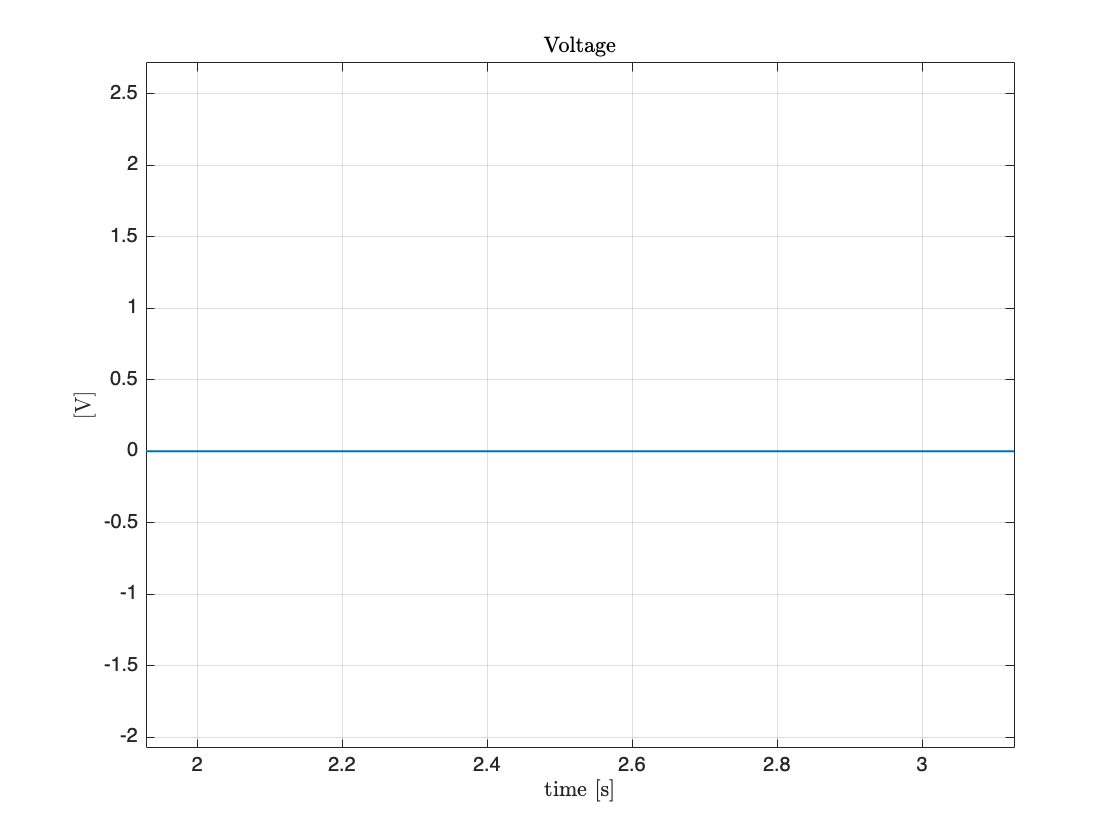

% plot the voltage signal
figure,plot(Time_vec_sim(1:N_sim),uin_sim,LineWidth=1);
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')
grid on

% plot state
figure,plot(Time_vec_sim,ysim(1,:),Time_vec_sim(1:N_sim),ysim(2,:),Time_vec_sim(1:N_sim),ysim(3,:),Time_vec_sim(1:N_sim),ysim(4,:),LineWidth=1)
legend("$\theta$","$\alpha$","$\dot{\alpha}$","$\dot{\theta}$",'Interpreter','latex')
title('Simulated State','Interpreter','latex')
xlabel('time [s]','Interpreter','latex')
ylabel("[rad], [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

### Observer 

back to Index

The specifications that we could impose in simpulation to design a good enough observer were the following:

- The settling time on the estimation $\dot{\alpha}$ (worst performances of the observer, lack of measurement associated to this variable) was required to be within $10,15\;%$ of the mechanical settling time for the selected variable.

- Initial conditions for the observer set at the equilibrium, always.

Mention the fact that differently from the controller design, the simulation results were less efficient in the real setup (because of noises amplifications when the filter was too fast and so on) and required further tuning in laboratory. Current Plots show the behaviour after the crafting of parameters in the lab sessions.

`sim_esp1111`

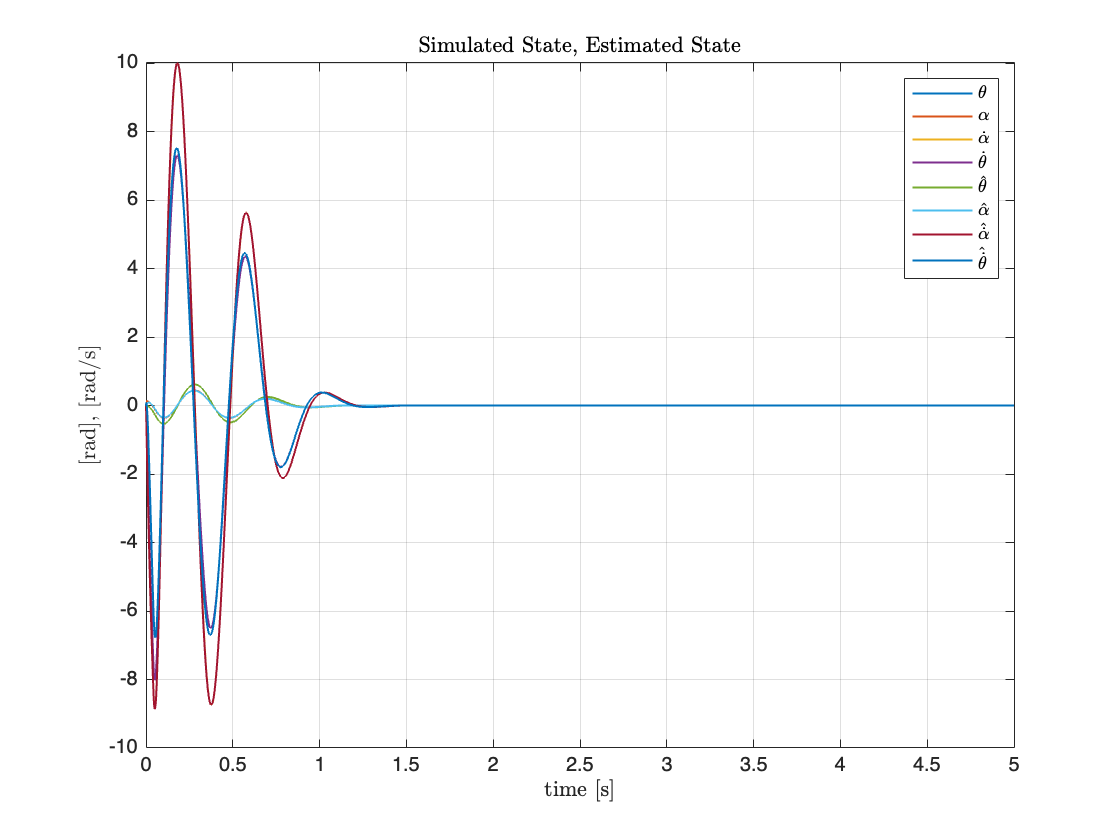

% plot estimated and simulated state all together
figure, plot(Time_vec_sim,ysim(1,:),Time_vec_sim,ysim(2,:),Time_vec_sim,ysim(3,:),Time_vec_sim,ysim(4,:),Time_vec_sim,xhat_sim(1,:),Time_vec_sim,xhat_sim(2,:),Time_vec_sim,xhat_sim(3,:),Time_vec_sim,xhat_sim(4,:),LineWidth=1)
legend("$\theta$","$\alpha$","$\dot{\alpha}$","$\dot{\theta}$","$\hat{\theta}$","$\hat{\alpha}$","$\hat{\dot{\alpha}}$","$\hat{\dot{\theta}}$",'Interpreter','latex')
title('Simulated State, Estimated State','Interpreter','latex')
xlabel('time [s]','Interpreter','latex')
ylabel("[rad], [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

% plot theta - theta_est
figure,plot(Time_vec_sim,ysim(1,:),Time_vec_sim(1:N_sim),xhat_sim(1,1:N_sim),LineWidth=1)
title('$\theta$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\theta (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

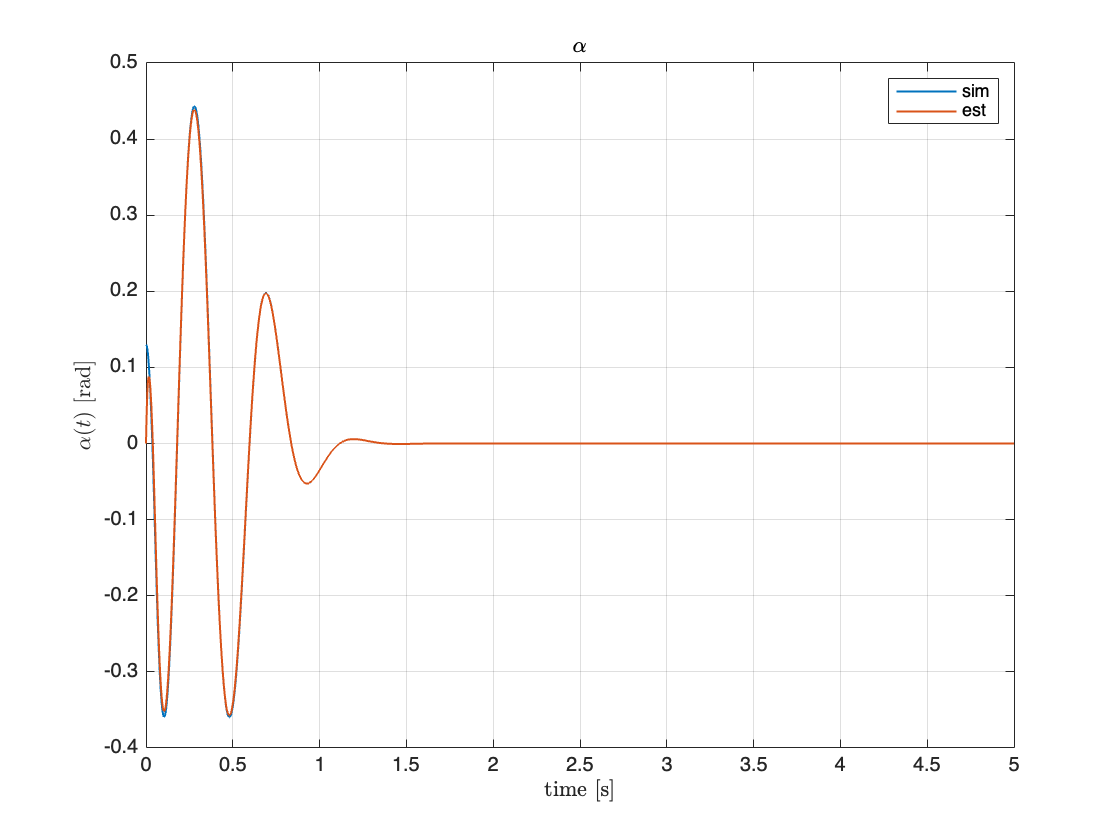


% plot alpha - alpha_est
figure,plot(Time_vec_sim(1:N_sim),ysim(2,:),Time_vec_sim(1:N_sim),xhat_sim(2,1:N_sim),LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\alpha (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

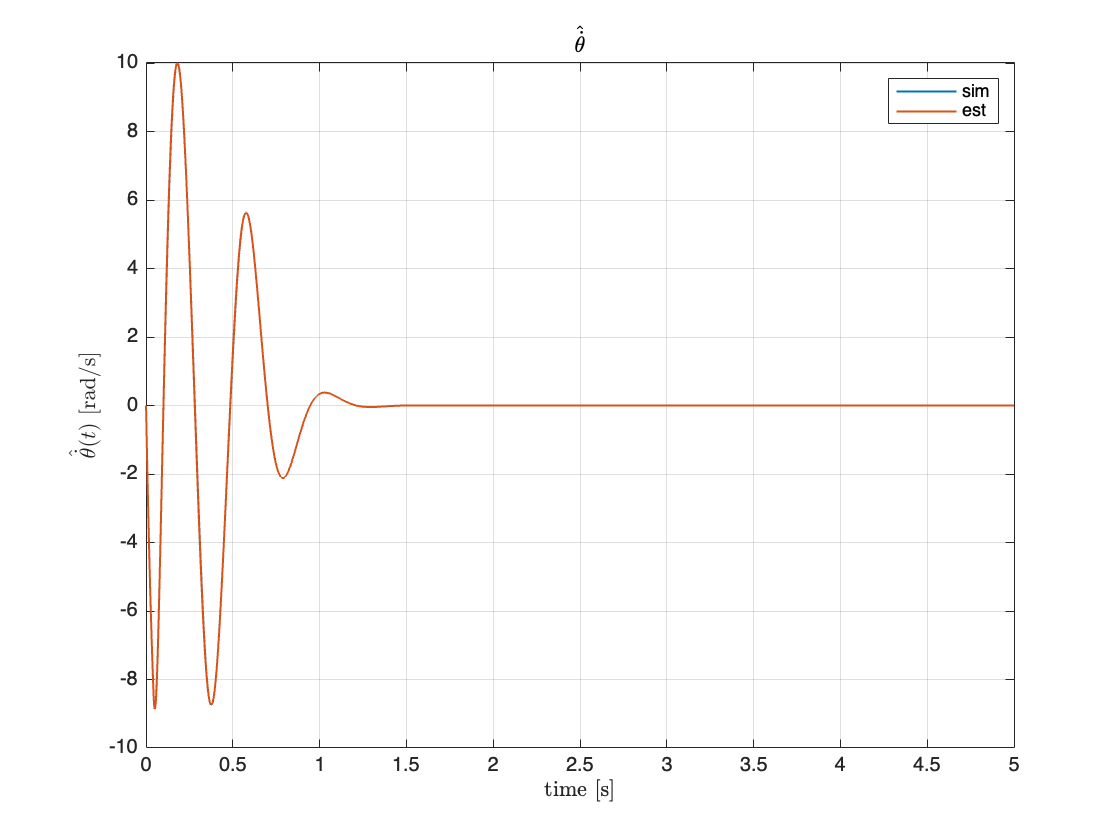

% plot theta_dot_est 
figure,plot(Time_vec_sim,ysim(3,:),Time_vec_sim(1:N_sim),xhat_sim(3,1:N_sim),LineWidth=1)
title('$\hat{\dot{\theta}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\theta}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

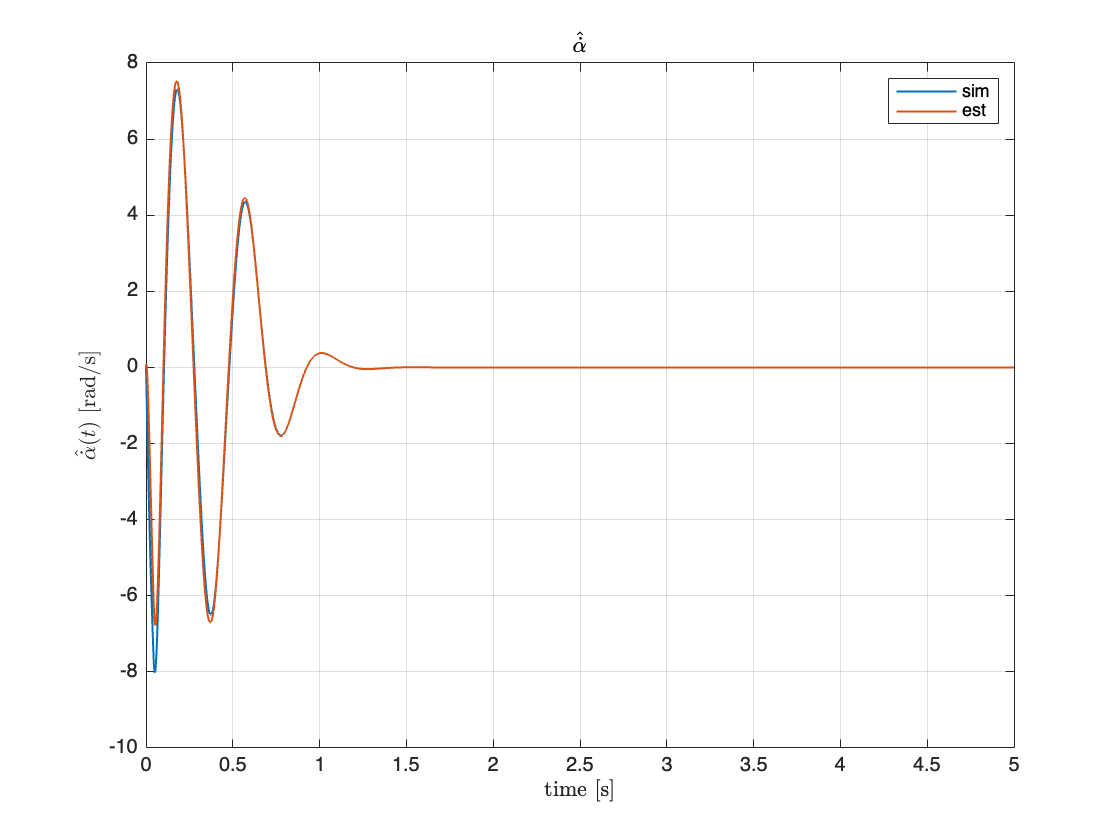

% plot alpha_dot_est
figure,plot(Time_vec_sim(1:N_sim),ysim(4,:),Time_vec_sim(1:N_sim),xhat_sim(4,1:N_sim),LineWidth=1)
title('$\hat{\dot{\alpha}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\alpha}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

## LQ Controller (only with KF during the design)

back to Index

- `sim_esp2222`

- 
$$\alpha =0\ldotp 3\;\left\lbrack \textrm{rad}\right\rbrack$$


#### Specifications

- 
$$e_{\infty } =0\;$$


- settling time $t_s \le 1\ldotp 5\;\left\lbrack s\right\rbrack$ in worst conditions on alpha ($e<0\ldotp 02\times \left|y_{\textrm{final}} -y_{\textrm{initial}} \right|$) -> **Remark: **only alpha starts from a value which is different from 0 so the settling time with this definition can be used only for $\alpha$ variable. We can mention that, once this condition was satisfied we seen by inspection that the other state variable were enough close to zero. To be more precise I would still report the values for all the sate variables at the time instant at which the $\alpha$ can be considered to have been stabilized.

- Voltage allowed to saturate during the whole manuvre just for maximum $0\ldotp 1\;\left\lbrack s\right\rbrack$ time intervals.

[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim,theta_ref_sim] = sim_data_processing(2222);
z0_sim

z0_sim =          0
    0.3000
         0
         0


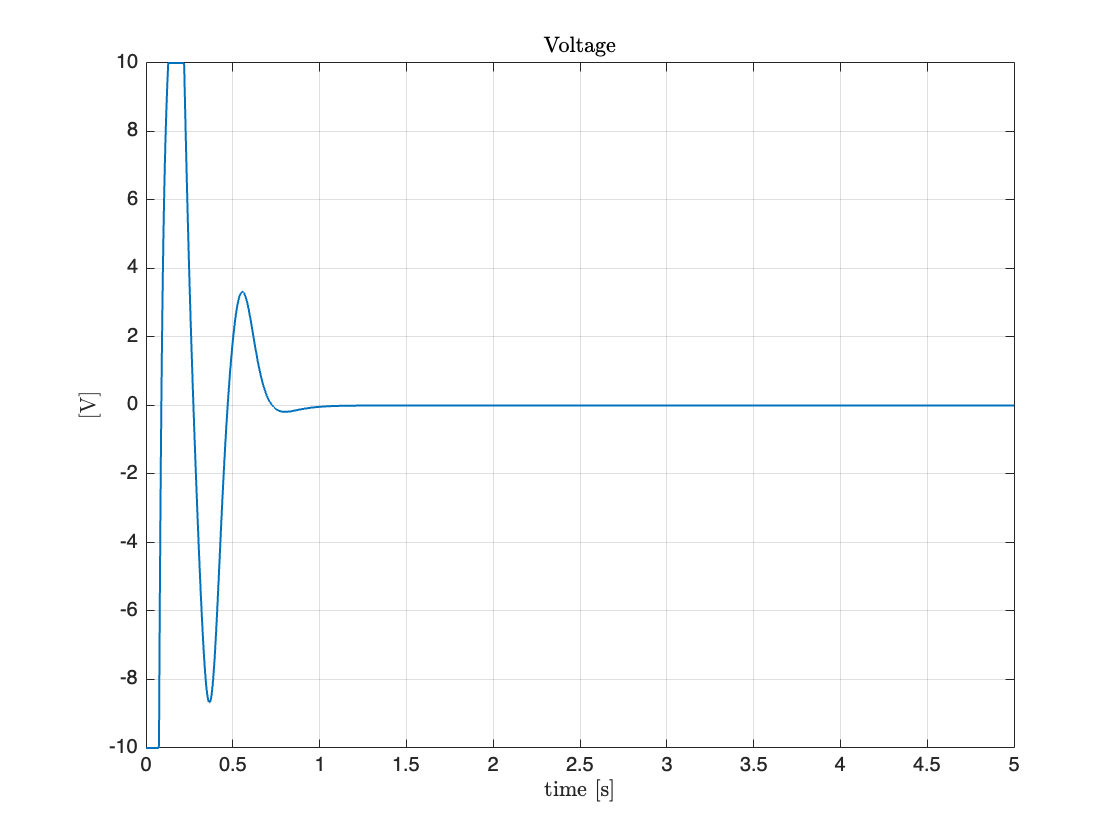

% plot the voltage signal
figure,plot(Time_vec_sim(1:N_sim),uin_sim,LineWidth=1);
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')
grid on

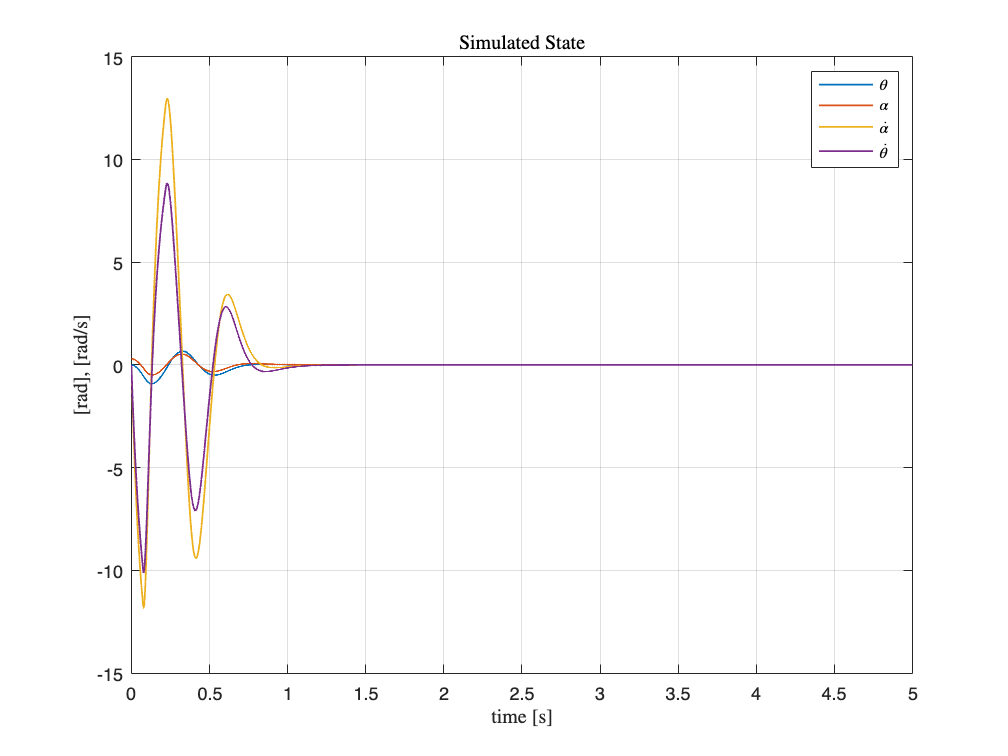

% plot state
figure,plot(Time_vec_sim,ysim(1,:),Time_vec_sim(1:N_sim),ysim(2,:),Time_vec_sim(1:N_sim),ysim(3,:),Time_vec_sim(1:N_sim),ysim(4,:),LineWidth=1)
legend("$\theta$","$\alpha$","$\dot{\alpha}$","$\dot{\theta}$",'Interpreter','latex')
title('Simulated State','Interpreter','latex')
xlabel('time [s]','Interpreter','latex')
ylabel("[rad], [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

### Kalman Filter

back to Index

`sim_esp2222`

Same specifications of the Observer.

Mention the fact that differently from the controller design, the simulation results were less efficient in the real setup (because of noises amplifications when the filter was too fast and so on) and required further tuning in laboratory. Current Plots show the behaviour after the crafting of parameters in the lab sessions.

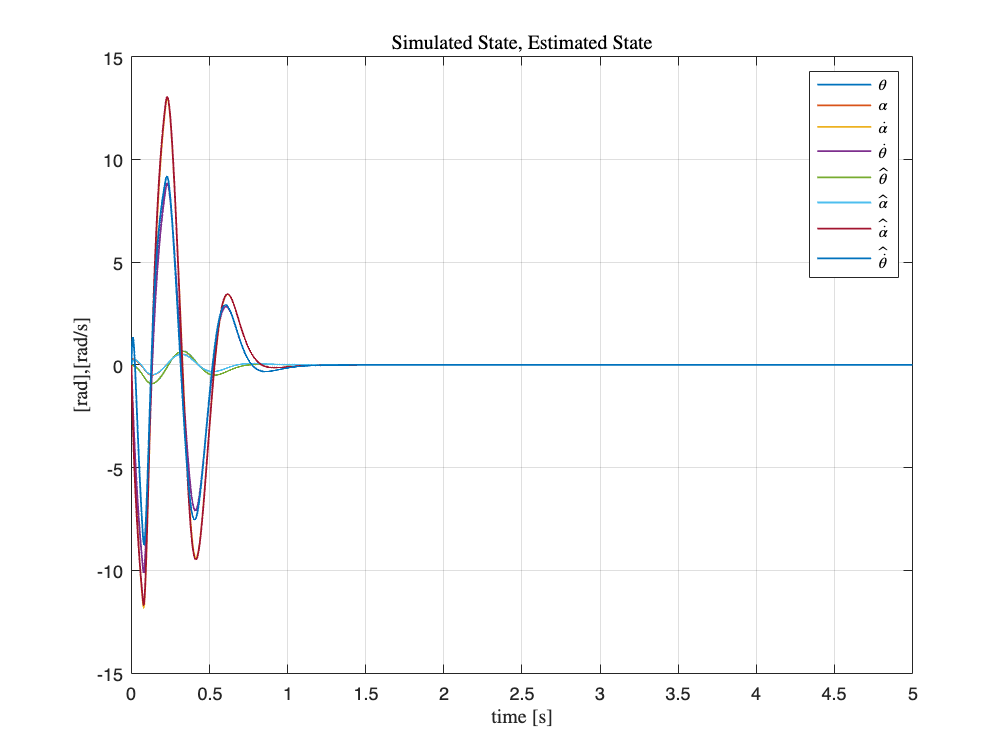

% plot estimated and simulated state all together
figure, plot(Time_vec_sim,ysim(1,:),Time_vec_sim,ysim(2,:),Time_vec_sim,ysim(3,:),Time_vec_sim,ysim(4,:),Time_vec_sim,xhat_sim(1,:),Time_vec_sim,xhat_sim(2,:),Time_vec_sim,xhat_sim(3,:),Time_vec_sim,xhat_sim(4,:),LineWidth=1)
legend("$\theta$","$\alpha$","$\dot{\alpha}$","$\dot{\theta}$","$\hat{\theta}$","$\hat{\alpha}$","$\hat{\dot{\alpha}}$","$\hat{\dot{\theta}}$",'Interpreter','latex')
title("Simulated State, Estimated State",'Interpreter','latex')
xlabel('time [s]','Interpreter','latex')
ylabel("[rad],[rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

% plot theta - theta_est
figure,plot(Time_vec_sim,ysim(1,:),Time_vec_sim(1:N_sim),xhat_sim(1,1:N_sim),LineWidth=1)
title('$\theta$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\theta (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on


% plot alpha - alpha_est
figure,plot(Time_vec_sim(1:N_sim),ysim(2,:),Time_vec_sim(1:N_sim),xhat_sim(2,1:N_sim),LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\alpha (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

% plot theta_dot_est 
figure,plot(Time_vec_sim,ysim(3,:),Time_vec_sim(1:N_sim),xhat_sim(3,1:N_sim),LineWidth=1)
title('$\hat{\dot{\theta}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\theta}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

% plot alpha_dot_est
figure,plot(Time_vec_sim(1:N_sim),ysim(4,:),Time_vec_sim(1:N_sim),xhat_sim(4,1:N_sim),LineWidth=1)
title('$\hat{\dot{\alpha}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\alpha}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

# Tracking Controllers

## Pole Placement for tracking

back to Index

- `sim_esp3333`

- 
$$\alpha =0\ldotp 13\;\left\lbrack \textrm{rad}\right\rbrack$$


#### Specifications (here we need to focus on the behaviour of $\theta$ over $\alpha \;$since the goal is to control that variable, the control on alpha provided by the tracking controllers can be inspected by tracking a 0 reference)

- 
$$e_{\infty } =0\;$$


- settling time $t_s \le 1\ldotp 5\;\left\lbrack s\right\rbrack$ not from initial conditions but from a steady state to the other steady state ($e<0\ldotp 02\times \left|y_{\textrm{final}} -y_{\textrm{initial}} \right|$) -> **Remark: **here we need to compute this quantity on $\theta$ which is the controlled variable of interest!!! 

- overshoot within $5\;%$ as in frequency based design (defined when reaching the goal position)

- Limits in the inverse reponse not considered, mention however the value of the inverse response on $\theta$

- Voltage allowed to saturate during the whole manuvre just for maximum $0\ldotp 1\;\left\lbrack s\right\rbrack$ time intervals.

### Tracking of a square wave

back to Index

t_max = 20;
[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim,theta_ref_sim] = sim_data_processing(3333);
z0_sim

z0_sim =          0
    0.1300
         0
         0


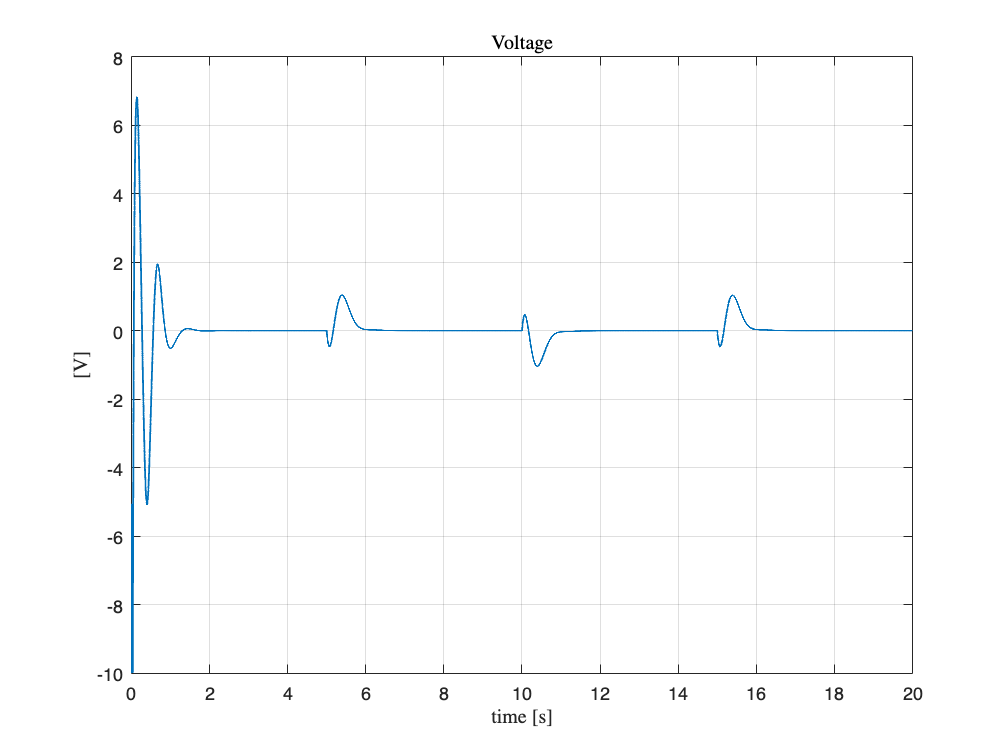

% plot the voltage signal
figure,plot(Time_vec_sim(1:N_sim),uin_sim,LineWidth=1);
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')
grid on

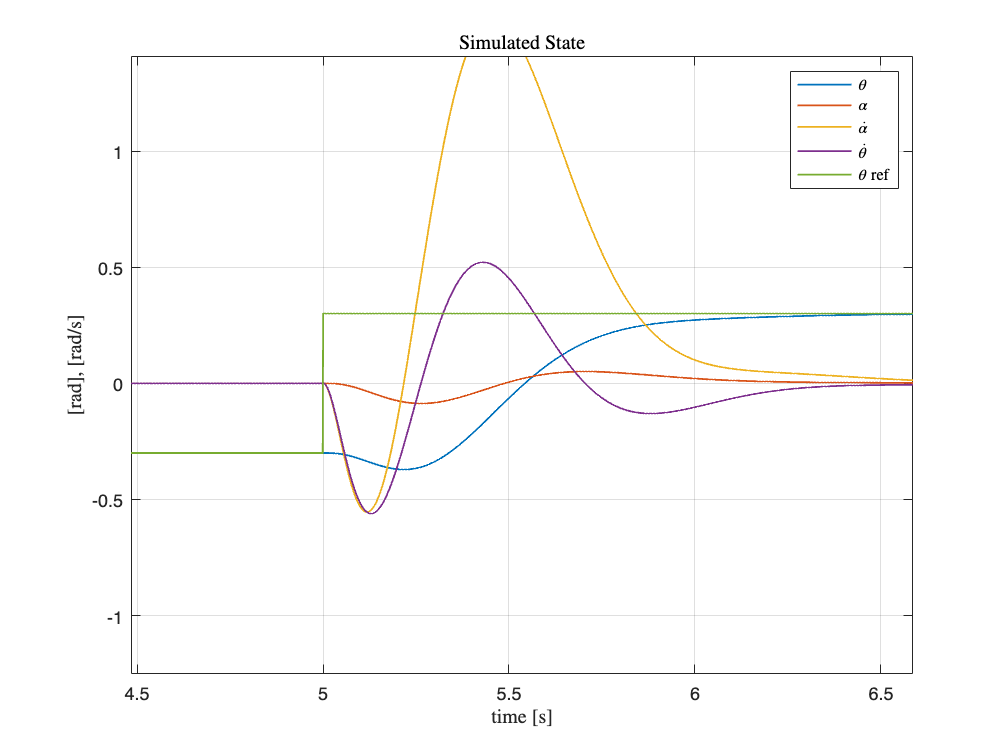

% plot state
figure,plot(Time_vec_sim,ysim(1,:),Time_vec_sim(1:N_sim),ysim(2,:),Time_vec_sim(1:N_sim),ysim(3,:),Time_vec_sim(1:N_sim),ysim(4,:),Time_vec_sim(1:N_sim),theta_ref_sim,LineWidth=1)
legend("$\theta$","$\alpha$","$\dot{\alpha}$","$\dot{\theta}$","$\theta$ ref",'Interpreter','latex')
title('Simulated State','Interpreter','latex')
xlabel('time [s]','Interpreter','latex')
ylabel("[rad], [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

### Tracking of the 0 (basically stabilization)

back to Index

This simulation was needed to compare the stabilizing properties of the tracking controller with respect to the ones specifically designed for stabilization. Specifications were not formulated for this case, just checked that everything was within acceptable ranges.

- `sim_esp3330`

Compare with performances in the stabilization case. The stabilizing action is a bit slower.

t_max = 5;
[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim,theta_ref_sim] = sim_data_processing(3330);
z0_sim

z0_sim =          0
    0.1300
         0
         0


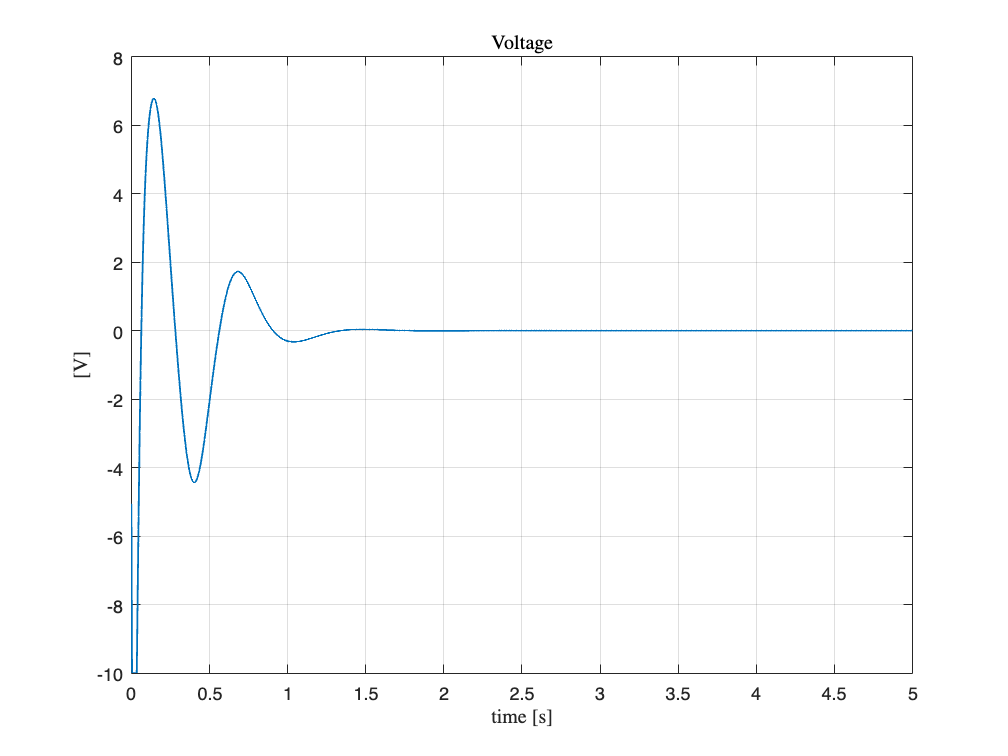

% plot the voltage signal
figure,plot(Time_vec_sim(1:N_sim),uin_sim,LineWidth=1);
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')
grid on

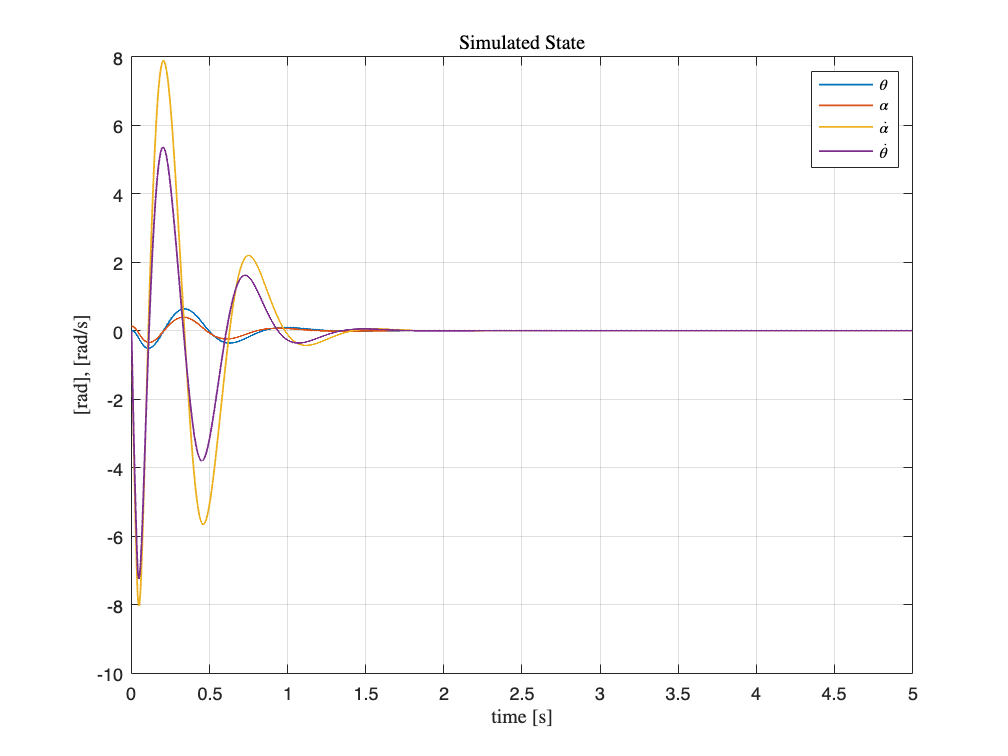

% plot state
figure,plot(Time_vec_sim,ysim(1,:),Time_vec_sim(1:N_sim),ysim(2,:),Time_vec_sim(1:N_sim),ysim(3,:),Time_vec_sim(1:N_sim),ysim(4,:),LineWidth=1)
legend("$\theta$","$\alpha$","$\dot{\alpha}$","$\dot{\theta}$",'Interpreter','latex')
title('Simulated State','Interpreter','latex')
xlabel('time [s]','Interpreter','latex')
ylabel("[rad], [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

## LQ Controller for Tracking

back to Index

- `sim_esp4444`

- 
$$\alpha =0\ldotp 3\;\left\lbrack \textrm{rad}\right\rbrack$$


#### Specifications (here we need to focus on the behaviour of $\theta$ over $\alpha \;$since the goal is to control that variable, the control on alpha provided by the tracking controllers can be inspected by tracking a 0 reference)

- 
$$e_{\infty } =0\;$$


- settling time $t_s \le \;2\;\left\lbrack s\right\rbrack$ not from initial conditions but from a steady state to the other steady state ($e<0\ldotp 02\times \left|y_{\textrm{final}} -y_{\textrm{initial}} \right|$) -> **Remark: **here we need to compute this quantity on $\theta$ which is the controlled variable of interest!!! 

 The settling time specification has been set as less stringent in order to make the controller more robust with respect to disturbances imposed during tracking with respect to the Pole Placement counterpart.

- overshoot within $5\;%$ as in frequency based design (defined when reaching the goal position)

- Limits in the inverse reponse not considered, mention however the value of the inverse response on $\theta$

- Voltage allowed to saturate during the whole manuvre just for maximum $0\ldotp 1\;\left\lbrack s\right\rbrack$ time intervals.

- mention that these specifications were formulated for a specific input signal.

### Tracking of a square wave

back to Index

t_max = 20;
[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim,theta_ref_sim] = sim_data_processing(4444);
z0_sim

z0_sim =          0
    0.3000
         0
         0


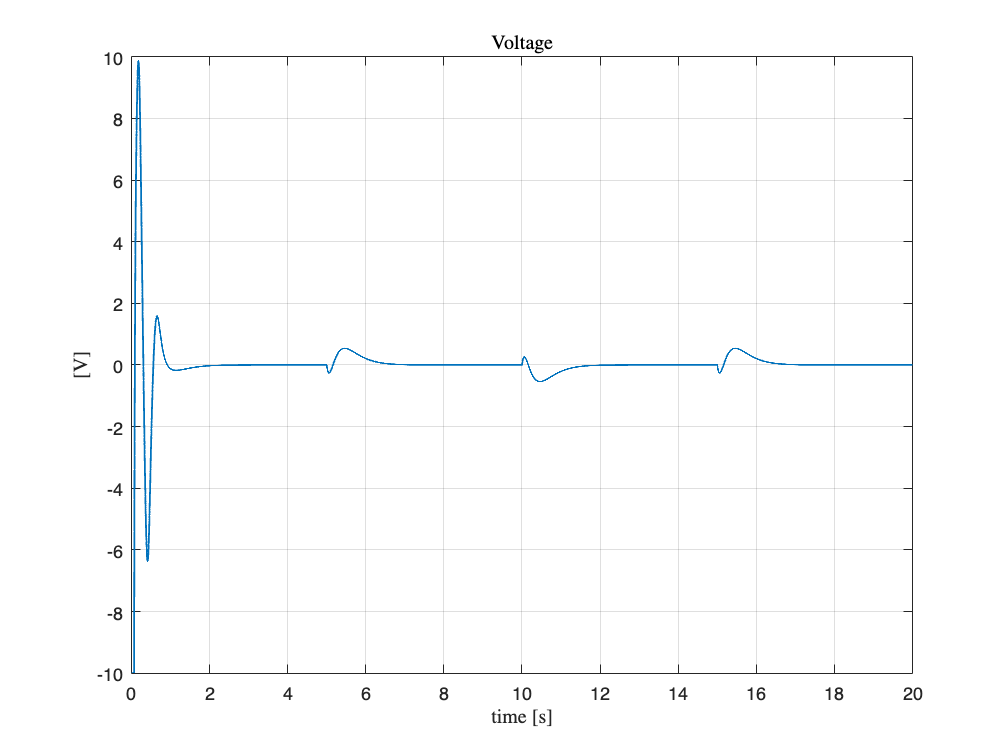

% plot the voltage signal
figure,plot(Time_vec_sim(1:N_sim),uin_sim,LineWidth=1);
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')
grid on

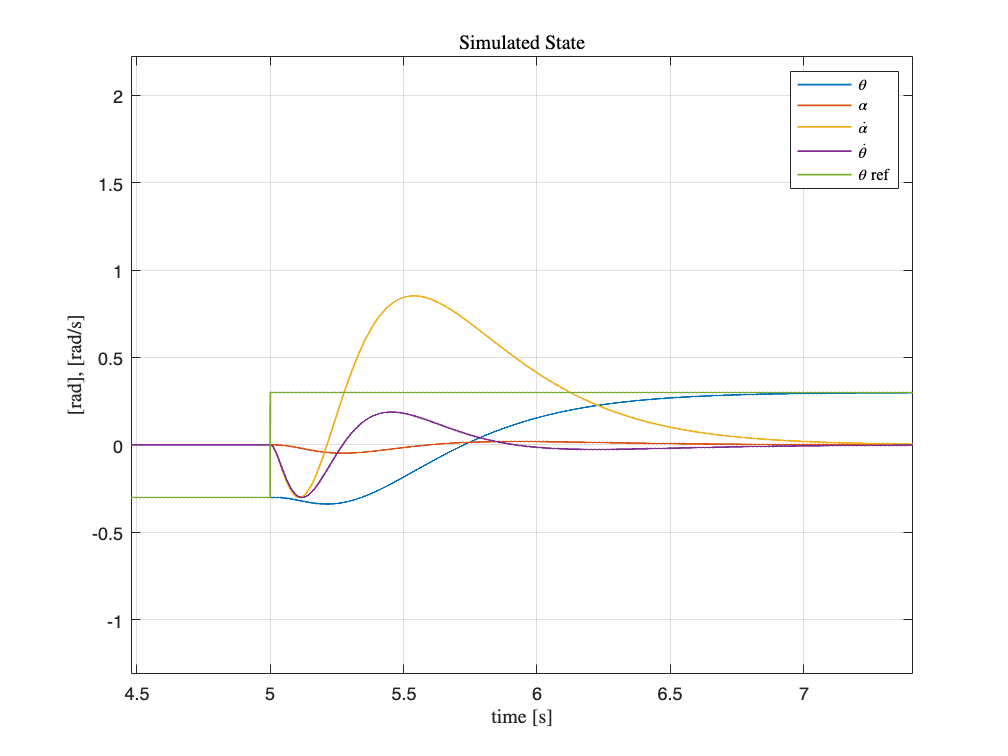

% plot state
figure,plot(Time_vec_sim,ysim(1,:),Time_vec_sim(1:N_sim),ysim(2,:),Time_vec_sim(1:N_sim),ysim(3,:),Time_vec_sim(1:N_sim),ysim(4,:),Time_vec_sim(1:N_sim),theta_ref_sim,LineWidth=1)
legend("$\theta$","$\alpha$","$\dot{\alpha}$","$\dot{\theta}$","$\theta$ ref",'Interpreter','latex')
title('Simulated State','Interpreter','latex')
xlabel('time [s]','Interpreter','latex')
ylabel("[rad], [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

### Tracking of the 0 (Basicallty stabilization)

back to Index

This simulation was needed to compare the stabilizing properties of the tracking controller with respect to the ones specifically designed for stabilization. Specifications were not formulated for this case, just checked that everything was within acceptable ranges.

- `sim_esp4440`

Compare with performances in the stabilization case. The stabilizing action is a bit slower.

t_max = 5;
[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim,theta_ref_sim] = sim_data_processing(4440);
z0_sim

z0_sim =          0
    0.3000
         0
         0


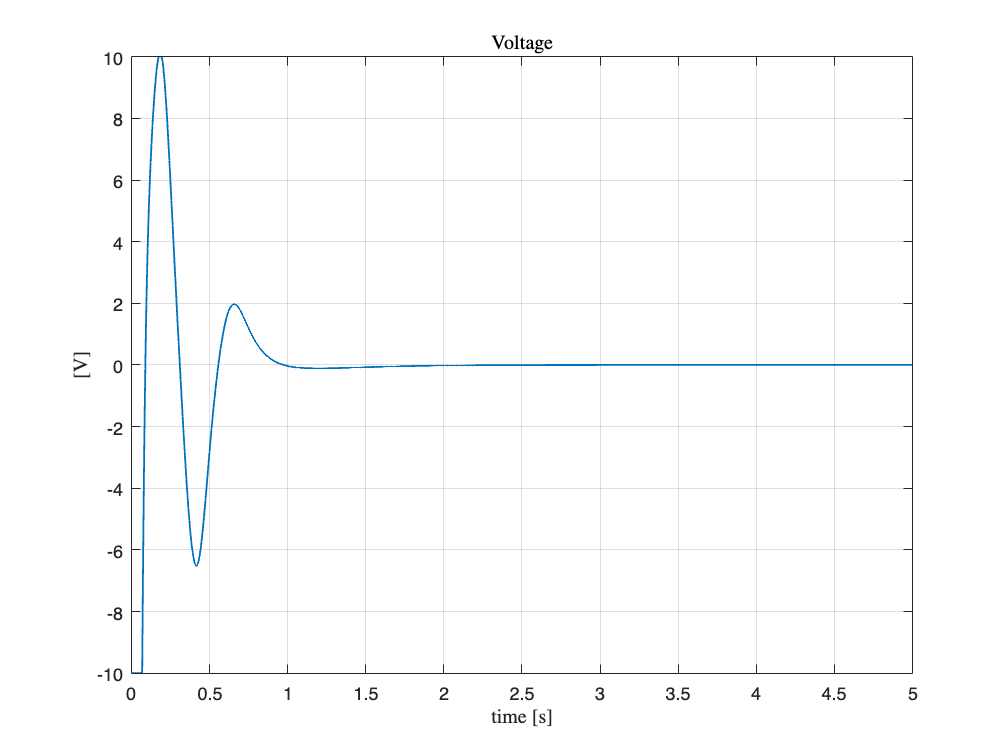

% plot the voltage signal
figure,plot(Time_vec_sim(1:N_sim),uin_sim,LineWidth=1);
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')
grid on

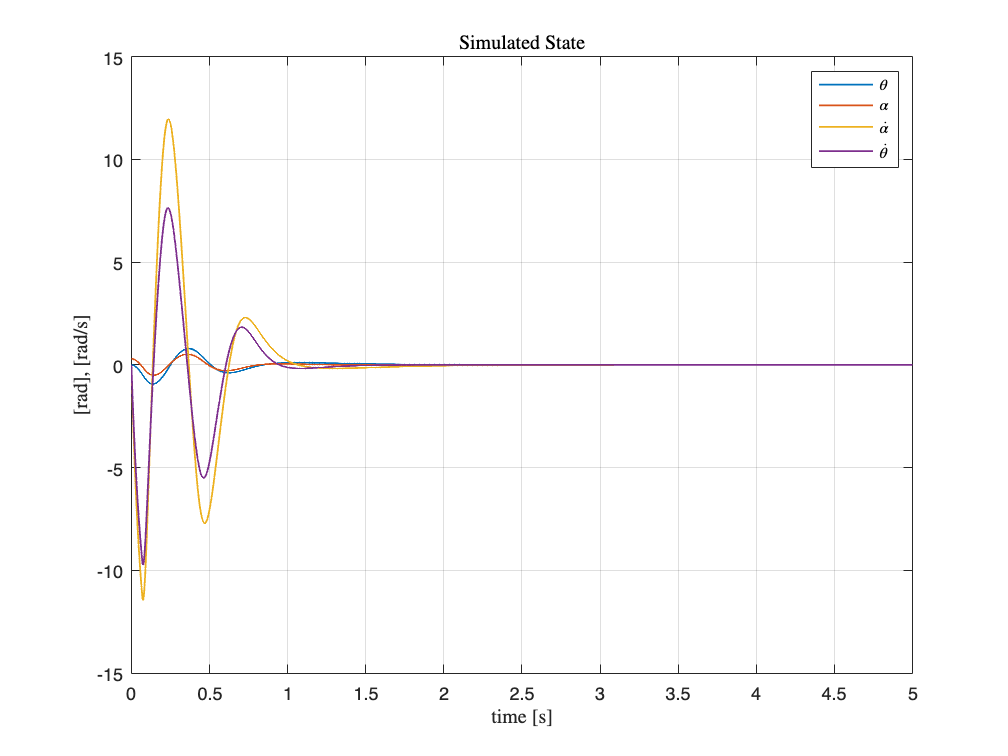

% plot state
figure,plot(Time_vec_sim,ysim(1,:),Time_vec_sim(1:N_sim),ysim(2,:),Time_vec_sim(1:N_sim),ysim(3,:),Time_vec_sim(1:N_sim),ysim(4,:),LineWidth=1)
legend("$\theta$","$\alpha$","$\dot{\alpha}$","$\dot{\theta}$",'Interpreter','latex')
title('Simulated State','Interpreter','latex')
xlabel('time [s]','Interpreter','latex')
ylabel("[rad], [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

# Robustness of tracking controllers with respect to disturbances during the tracking manuvre.

Here we want to place the data that allow us to have a quantitative comparison of how much more robust is the LQ for tracking with respect to the PP.

# Auxiliary Functions

function [Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim,theta_ref_sim] = sim_data_processing(n_exp)
% first we want to load the corresponding file
simu = load('sim_esp'+string(n_exp)+'.mat');
% want row vectors
Time_vec_sim = (simu.out.tout)';
N_sim = length(Time_vec_sim); % number of samples of the measurement

sim_data = simu.out.simout.Data;

% want row vectors !!!
uin_sim = sim_data(:,1)'; % input voltages signal collected from measurement % place negative sign

theta = sim_data(:,2)';
alpha = sim_data(:,3)';
theta_dot = sim_data(:,4)';
alpha_dot = sim_data(:,5)';

theta_est = sim_data(:,6)';
alpha_est = sim_data(:,7)';
theta_dot_est = sim_data(:,8)';
alpha_dot_est = sim_data(:,9)';

% check on wether refference signal was saved
sz = size(sim_data);

if sz(2) > 9
    theta_ref_sim = sim_data(:,10)';
else
    theta_ref_sim = zeros(N_sim,1)';
end

ysim = [theta;alpha;theta_dot;alpha_dot]; % measured state
xhat_sim = [theta_est;alpha_est;theta_dot_est;alpha_dot_est]; % estimated state

z0_sim = [ysim(1,1); ysim(2,1); 0; 0]; % initial conditions given the modeling conventions

end
